# **Vision Artificial. GIEC - Sistemas de Vision Artificial. GIC**

# **Tema 3. Segmentación supervisada del histograma**

**  Departamento de Electrónica. Universidad de Alcalá.**

## 1.1. Segmentación basada en el histograma, supervisada, con umbral global

En el siguiente ejemplo se genera una imagen con objetos de distintos colores que se pueden segmentar definiendo los umbrales correctos en el histograma.

close all
clear all
clc

% Generación de la imagen con objetos de distintos colores (inicialmente
% uniformes, con ruido añadido posteriormente)

BW1=zeros(256,256); %Crea imagen (toda a nivel negro)
BW1(30:60,30:90)=1; %Crea rectangulo blanco dentro de BW1
BW1(120:220,130:200)=0.7; %Crea rectangulo gris claro dentro de BW1
J=imnoise(BW1,'gaussian',0,0.0074718); 	%Introduce ruido gaussiano en BW1
K=wiener2(J,[5 5]); %Filtra la imagen
figure; imshowpair(BW1,K,'montage') ;  title('Imagenes original y filtrada');

figure;imhist(K);xlabel('nivel de gris');ylabel('Nº de píxeles');

A la vista del histograma, se observa como aplicando un umbral de 0.2, se segmentarán (previsiblemente) todos los objetos de la imagen (dado que el objeto más numeroso en nº de píxeles es el fondo, cercano al valor 0 (negro):

% Um=(K >= 0.2); %Imagen binaria con pixels a "1" donde K >= 0.2 y "0" en el resto de pixels.

Um=(K >= 0.66); %Imagen binaria con pixels a "1" donde K >= 0.2 y "0" en el resto de pixels.
figure; imshow(Um); title('Segmentación con umbral=0.2');

Utilizando un único umbral NO se pueden segmentar todos los objetos, debemos utilizar un umbral entre cada par de objetos (en este caso, entre cada par de gaussianas).

thresh = [0.5 0.85]; % vector de umbrales
BW_seg2 = imquantize(K,thresh); % Segmenta la imagen utilizando los umbrales indicados en thresh
RGB_seg2 = label2rgb(BW_seg2); % Convierte la imagen segmentada en una imagen en color usando: label2rgb   
imshowpair(K,RGB_seg2,'montage')   
title('Imagen filtrada segmentada (método supervisado lineal)');

**Pruebe a segmentar los distintos objetos en imágenes distintas, a cambiar el nivel de gris de los objetos, los valores de los umbrales, etc.**

## 1.2.	Segmentación supervisada por modelos gaussianos (no lineal)

El mayor problema de la segmentación anterior es el cálculo de los umbrales. Además, los objetos se suelen distribuir en el histograma de forma gaussiana. Se puede hacer una segmentación mejor caracterizando los niveles de gris de los objetos de la imagen y del fondo mediante modelos basados en funciones de densidad de probabilidad gaussianas (véase la Figura 1) y obteniendo, luego, el umbral óptimo o viendo el grado de pertenencia de un píxel (con un determinado nivel de gris) a uno u otro modelo (objeto, fondo...) y clasificando después el píxel al modelo cuyo grado de pertenencia es mayor.

Para la creación de estos modelos gaussianos de los objetos únicamente se necesitan los parámetros ***media ****m* y ***varianza (desviación típica) ***$\sigma$ de los niveles de gris del objeto, que podemos estimar a partir de un conjunto significativo de puntos de cada uno de ellos.

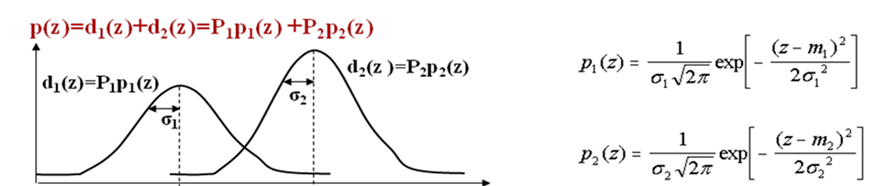

Figura 1.- Histograma con dos objetos modelados mediante funciones gaussianas

filename = 'rice.tif'; % 'saturn.tif';

% El siguiente fragmento de código carga imágenes de distintos formatos y
% los convierte a escala de grises, formato double, para poder realizar las 
% operaciones requeridas. Se podría seguir un esquema paralelo y traducir 
% cada tipo de imagen al formato de destino que necesitemos.

info = imfinfo(filename)
if strcmp(info.ColorType,'indexed')
    [Y,map] = imread(filename);
    Z = ind2gray(Y,map);
    X=im2double(Z);
elseif strcmp(info.ColorType,'truecolor')
    rgb=imread(filename);
    Z=rgb2gray(rgb);
    X=im2double(Z);
elseif  strcmp(info.ColorType,'grayscale')
    X=im2double(imread(filename)); 
else
    X=imread(filename);
end

imshow(X)
figure;imhist(X);

La función **impixel **permite seleccionar un conjunto de puntos representativos del fondo y de los granos de la imagen 'rice.tif' y obtener el valor de gris de los mismos. La selección se realizará haciendo click con el botón izquierdo del ratón (al menos en 5 píxeles de cada clase), y se finalizará pulsando *enter*.

disp('Selecciona 1º, con el raton (botón izq.), unos cuantos pixels de fondo. Luego enter.');
disp( 'Selecciona después unos cuantos pixels de objetos. Luego enter');
fig=figure
imshow(X);title('Selecciona pixeles del fondo.')
hold on
val=impixel(X)
hold off
close(fig)
fondo=val;

fig=figure
imshow(X);title('Selecciona pixeles de los objetos')
hold on
val=impixel(X);
hold off
close(fig)
granos=val;


A partir de estos píxeles, las siguientes líneas de código obtienen los estadísticos ***media*** y ***varianza (desvación típica)*** de los dos conjuntos de píxeles (clase fondo y clase grano):

mf=mean(fondo(:,1))  %Media de la clase fondo
mg=mean(granos(:,1)) %Media de la clase grano 

sf=std(fondo(:,1))   %Desviacion tipica de la clase fondo
if (sf==0) 
    sf=0.0000001  % para evitar problemas con la fórmula. También podría dejarse en 0 y modificarse la fórmula
end

sg=std(granos(:,1))  %Desviacion tipica de la clase grano
if (sg==0) 
    sg=0.0000001  % para evitar problemas con la fórmula. También podría dejarse en 0 y modificarse la fórmula
end

Las siguientes líneas visualizan la media de cada clase (de los píxeles elegidos como representativos) sobre el histograma global.

figure,
imhist(X);

hold on,
plot(mf, 0,'go','LineWidth',3); 
plot(mg, 0,'rx','LineWidth',3); 
title('Media del fondo y del objeto.');
hold off; 

Seguidamente, segmente la imagen clasificando cada píxel de la misma (en función de su nivel de gris) en el modelo para el cual la función densidad de probabilidad (fdp) sea mayor (grado de pertenencia mayor). Se suponen las clases equiprobables (P1=P2 en la Fig. 1).

tic %para computar cuanto tarda este algoritmo desde este punto

[maxX,maxY]=size(X);

S=zeros(maxX,maxY); %Imagen a segmentar S inicializada ceros (fondo -> todo negro)

for i=1:1:maxX 	%Para todas las filas de la imagen
    for j=1:1:maxY 	%Para todas las columnas de la imagen
        
        x=X(i,j); %Se toma cada pixel "x" de la imagen
        
        % se calcula el valor en la función densidad de probabilidad para
        % el valor "x" para cada clase.
        bayesf=(1/(sqrt(2*pi)*sf))*exp(-0.5*(x-mf)'*sf^(-2)*(x-mf)); %fdp normal
        %Nota.- Se puede poner (x-mf)' o (x-mf) pues es un número y (x-mf)= (x-mf)’
        bayesg=(1/(sqrt(2*pi)*sg))*exp(-0.5*(x-mg)'*sg^(-2)*(x-mg)); %fdp normal
        %Nota.- Se puede poner (x-mg)' o (x-mg) pues es un número y (x-mg)= (x-mg)’
        
        if bayesg >bayesf %Pixel en posicion (i,j) tiene  > pertenencia a la fdp normal clase grano
            S(i,j)=1; %Pone a "1" (blanco) el pixel en posicion (i,j) pues pertenece a la clase grano
        end
    end
end

figure,imshow(S);title('Imagen segmentada S');
toc %devuelve cuanto tardo el algoritmo desde el inicio del tic

El código con for anidados anterior se puede sustituir, aprovechando la capacidad de Matlab de trabajar **vectorial y matricialmente**, por este otro, más rápido, dónde se ha llamado SSS a la matriz con los resultados de la segmentación (en lugar de S)

tic %para computar cuanto tarda este algoritmo desde este punto

SSS=zeros(maxX,maxY); %Imagen a segmentar  inicializada ceros(fondo -> todo negro)
bayesf_total=(1/(sqrt(2*pi)*sf))*exp(-0.5*(X-mf)*sf^(-2).*(X-mf)); %fdp normal
bayesg_total=(1/(sqrt(2*pi)*sg))*exp(-0.5*(X-mg)*sg^(-2).*(X-mg)); %fdp normal
SSS= (bayesg_total > bayesf_total);
figure,imshow(SSS); title('Imagen segmentada SSS');
toc %devuelve cuanto tardo el algoritmo desde el inicio del tic

La siguiente instrucción devuelve un vector que contiene los índices de cada elemento distinto de cero en el array (S-SSS). Si es el conjunto vacío, significará que todos los píxeles de S y SSS son iguales, es decir, que con los dos métodos hemos obtenido el mismo resultado.

find (S-SSS)   